# Problema 1

## Formula trapezului

function integral = integrare_trapeze(f, a, b, divizari)

    pas = (b - a) / divizari; % pasul intre noduri
    puncte = linspace(a, b, divizari + 1); % genereaza nodurile
    valori = arrayfun(f, puncte); % evalueaza functia in fiecare nod

    % Aplica formula trapezului:
    integral = pas * (sum(valori) - 0.5 * (valori(1) + valori(end)));
end

## Formula dreptunghiului

function integral = integrare_dreptunghiuri(f, a, b, divizari)
    pas = (b - a) / divizari; % lungimea fiecarui dreptunghi
    mijloace = a + pas * (0.5 : 1 : divizari - 0.5); % vector cu puncte de mijloc

    evaluari = arrayfun(f, mijloace); % evalueaza functia in punctele de mijloc

    integral = pas * sum(evaluari); % suma ariilor dreptunghiurilor
end

## Formula lui Simpson

function integral = integrare_simpson(f, a, b, divizari)
    if rem(divizari, 2) ~= 0
        error('divizari trebuie sa fie par pentru regula Simpson.');
    end

    pas = (b - a) / divizari; % pasul intre noduri
    puncte = a + (0:divizari) * pas; % nodurile x0, x1, ..., xn
    valori = f(puncte); % evaluarea functiei in fiecare nod

    % Coeficienții:
    coef4 = sum(valori(2:2:end-1));
    coef2 = sum(valori(3:2:end-2));

    % Formula Simpson compusa:
    integral = pas/3 * (valori(1) + 4 * coef4 + 2 * coef2 + valori(end));
end

f = @(x) x.^2;       % functia de integrat
a = 0;
b = 1;
divizari = 10;       % numar subintervale
valoare_exacta = 1/3;


fprintf("Intervalul: [%g, %g]\n", a, b);

Intervalul: [0, 1]


fprintf("Numar de subintervale (divizari): %d\n\n", divizari);

Numar de subintervale (divizari): 10






rez_trapeze = integrare_trapeze(f, a, b, divizari);
rez_dreptunghi = integrare_dreptunghiuri(f, a, b, divizari);
rez_simpson = integrare_simpson(f, a, b, divizari);

% Trapeze
eroare_trapez = abs(rez_trapeze - valoare_exacta);
fprintf("Metoda TRAPEZELOR:\n");

Metoda TRAPEZELOR:


fprintf("→ Aproximare:      %.10f\n", rez_trapeze);

→ Aproximare:      0.3350000000


fprintf("→ Valoare exacta:  %.10f\n", valoare_exacta);

→ Valoare exacta:  0.3333333333


fprintf("→ Eroare absoluta: %.2e\n\n", eroare_trapez);

→ Eroare absoluta: 1.67e-03




% Dreptunghiuri
eroare_drept = abs(rez_dreptunghi - valoare_exacta);
fprintf("Metoda DREPTUNGHIURILOR (mijloc):\n");

Metoda DREPTUNGHIURILOR (mijloc):


fprintf("→ Aproximare:      %.10f\n", rez_dreptunghi);

→ Aproximare:      0.3325000000


fprintf("→ Valoare exacta:  %.10f\n", valoare_exacta);

→ Valoare exacta:  0.3333333333


fprintf("→ Eroare absoluta: %.2e\n\n", eroare_drept);

→ Eroare absoluta: 8.33e-04




% Simpson
eroare_simpson = abs(rez_simpson - valoare_exacta);
fprintf("Metoda SIMPSON:\n");

Metoda SIMPSON:


fprintf("→ Aproximare:      %.10f\n", rez_simpson);

→ Aproximare:      0.3333333333


fprintf("→ Valoare exacta:  %.10f\n", valoare_exacta);

→ Valoare exacta:  0.3333333333


fprintf("→ Eroare absoluta: %.2e\n", eroare_simpson);

→ Eroare absoluta: 0.00e+00


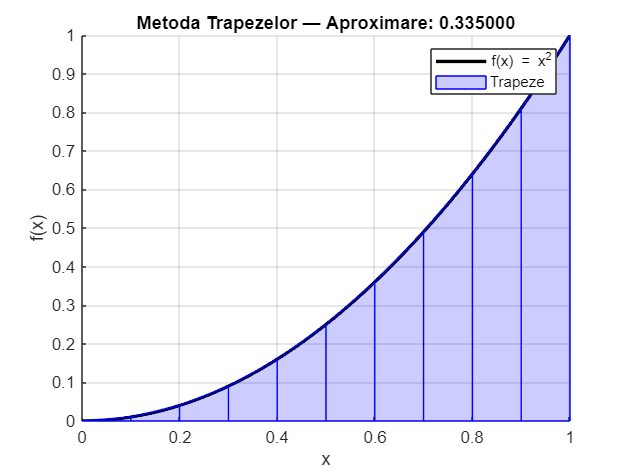







% PLOT GRAFIC

% Trapeze 
figure;
hold on;
plot(x_fine, y_fine, 'k', 'LineWidth', 2);
for i = 1:n
    x_trap = [x_nodes(i), x_nodes(i), x_nodes(i+1), x_nodes(i+1)];
    y_trap = [0, y_nodes(i), y_nodes(i+1), 0];
    fill(x_trap, y_trap, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'b');
end
title(sprintf('Metoda Trapezelor — Aproximare: %.6f', rez_trapeze));
legend('f(x) = x^2', 'Trapeze');
xlabel('x'); ylabel('f(x)');
grid on;
hold off;

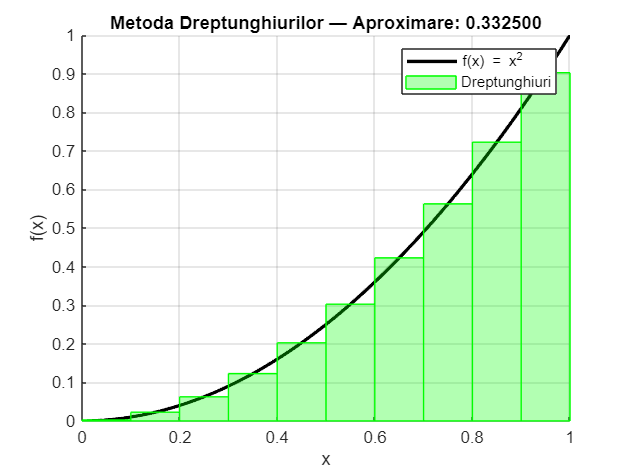


% Dreptunghiuri 
figure;
hold on;
plot(x_fine, y_fine, 'k', 'LineWidth', 2);
for i = 1:n
    x_rect = [x_nodes(i), x_nodes(i), x_nodes(i+1), x_nodes(i+1)];
    y_rect = [0, y_mijloc(i), y_mijloc(i), 0];
    fill(x_rect, y_rect, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'g');
end
title(sprintf('Metoda Dreptunghiurilor — Aproximare: %.6f', rez_dreptunghi));
legend('f(x) = x^2', 'Dreptunghiuri');
xlabel('x'); ylabel('f(x)');
grid on;
hold off;

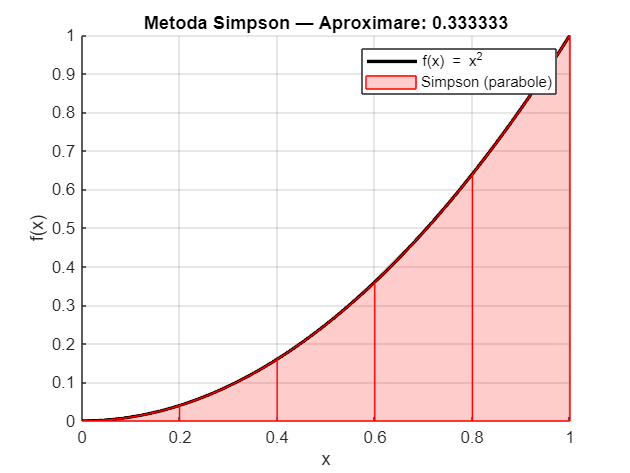


% Simpson
figure;
hold on;
plot(x_fine, y_fine, 'k', 'LineWidth', 2);
for i = 1:2:n-1
    x_parab = linspace(x_nodes(i), x_nodes(i+2), 100);
    y_parab = f(x_parab);
    fill([x_parab, fliplr(x_parab)], [y_parab, zeros(size(y_parab))], ...
        'r', 'FaceAlpha', 0.2, 'EdgeColor', 'r');
end
title(sprintf('Metoda Simpson — Aproximare: %.6f', rez_simpson));
legend('f(x) = x^2', 'Simpson (parabole)');
xlabel('x'); ylabel('f(x)');
grid on;
hold off;